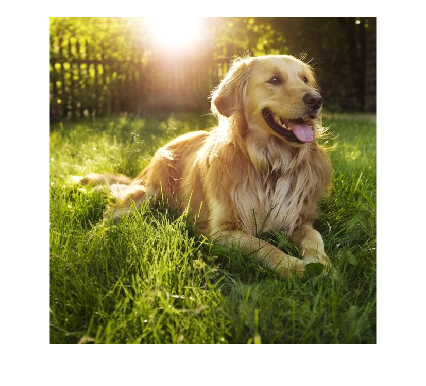

img = imread("squaredog.jpg");
imshow(img);

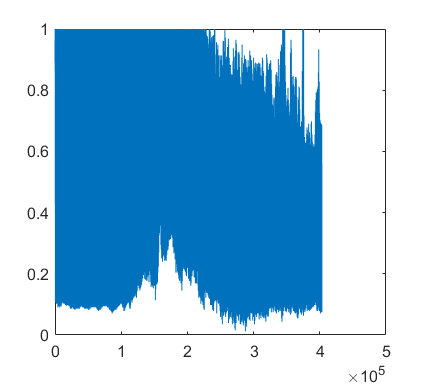


R = im2double(img(:,:,1));
G = im2double(img(:,:,2));
B = im2double(img(:,:,3));


LR = [];
for i = 1:635
    LR = [LR,R(i,:)];
end
plot(LR);

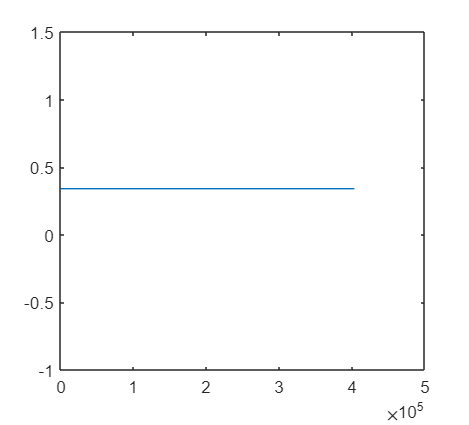


VAD = voiceActivityDetector;
[prob,x] = VAD(LR);
plot(prob);

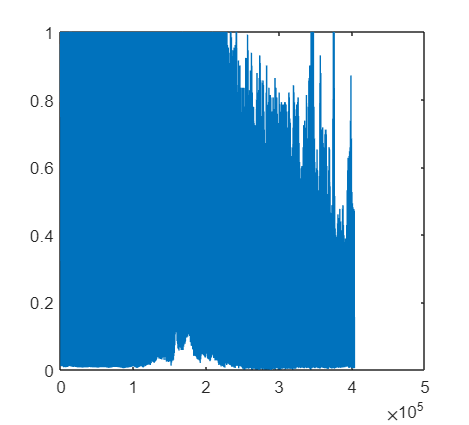

plot(x);

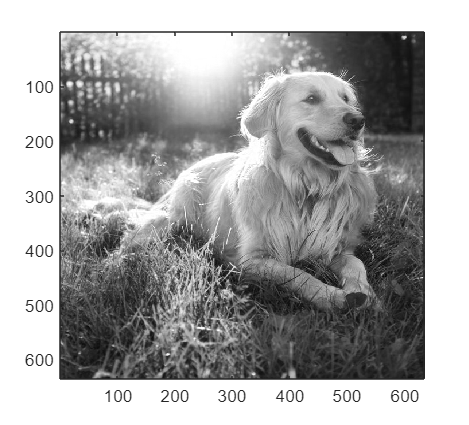


 for i = 1:635
     R(i,:) = LR((i-1)*635+ 1: i*635);
 end
imagesc(R)

%outimg = uint8(cat(3,R,G,B));
%imshow(outimg);
colormap("gray")

%imshow();

